x = [0,10,10, 20];
y = [0,0,10, 10];
path = Path(x,y,2,0.01);

Unable to perform assignment because the size of the left side is 1-by-1 and the size of the right side is 0-by-0.

Error in Path/calculateTransitions (line 83)
                t(i+1,1) = t(i,1) + obj.subsplines(i).getLength();

Error in Path (line 40)
           obj.transitions = obj.calculateTransitions();

len = path.getLength()
s = [0:.01:len];
[x1,y1] = path.getPoint(s);
figure();
plot(x1,y1,":x")


[xt,yt] = path.diff(7.99,1)

xt = 1.0000

yt = -3.8286e-09

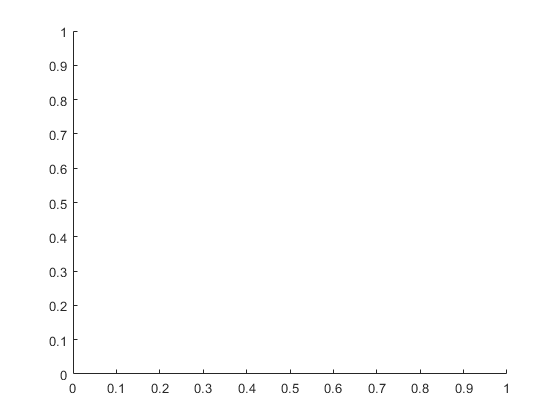

figure();
%plot(s,xt)
hold on;

%plot(s,yt)
figure();

b = BezierCurve([0,10,10],[0,0,10],2,0.01)

b =   BezierCurve with properties:

     startPoint: [1×1 struct]
       endPoint: [1×1 struct]
              r: 2
             dx: 0.0100
    curvePoints: [1×1 struct]
         length: 3.2464


s= [0.01:0.1:b.getLength()-0.01]

s =     0.0100    0.1100    0.2100    0.3100    0.4100    0.5100    0.6100    0.7100    0.8100    0.9100    1.0100    1.1100    1.2100    1.3100    1.4100    1.5100    1.6100    1.7100    1.8100    1.9100    2.0100    2.1100    2.2100    2.3100    2.4100    2.5100    2.6100    2.7100    2.8100    2.9100    3.0100    3.1100    3.2100


[x,y] = b.getPoint(s)

x =     8.0123    8.1332    8.2504    8.3637    8.4733    8.5790    8.6810    8.7791    8.8735    8.9641    9.0509    9.1338    9.2130    9.2884    9.3600    9.4278    9.4918    9.5520    9.6085    9.6611    9.7099    9.7549    9.7962    9.8336    9.8672    9.8971    9.9231    9.9454    9.9639    9.9785    9.9894    9.9965    9.9997


y =     0.0000    0.0023    0.0084    0.0182    0.0319    0.0494    0.0706    0.0957    0.1245    0.1571    0.1936    0.2338    0.2778    0.3257    0.3773    0.4327    0.4919    0.5549    0.6217    0.6923    0.7667    0.8449    0.9268    1.0126    1.1022    1.1956    1.2927    1.3937    1.4984    1.6070    1.7193    1.8354    1.9554


[xt,yt] = b.diff(s)                     

xt =     1.2283    1.1904    1.1524    1.1145    1.0765    1.0386    1.0006    0.9627    0.9247    0.8868    0.8488    0.8108    0.7729    0.7349    0.6970    0.6590    0.6211    0.5831    0.5452    0.5072    0.4693    0.4313    0.3934    0.3554    0.3174    0.2795    0.2415    0.2036    0.1656    0.1277    0.0897    0.0518    0.0138


yt =     0.0038    0.0417    0.0797    0.1177    0.1556    0.1936    0.2315    0.2695    0.3074    0.3454    0.3833    0.4213    0.4592    0.4972    0.5351    0.5731    0.6111    0.6490    0.6870    0.7249    0.7629    0.8008    0.8388    0.8767    0.9147    0.9526    0.9906    1.0285    1.0665    1.1044    1.1424    1.1804    1.2183


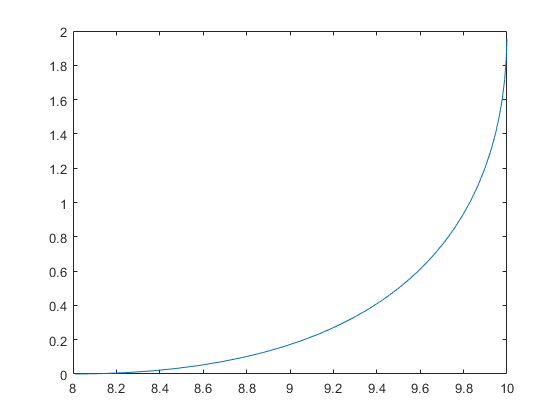

figure();
plot(x,y);

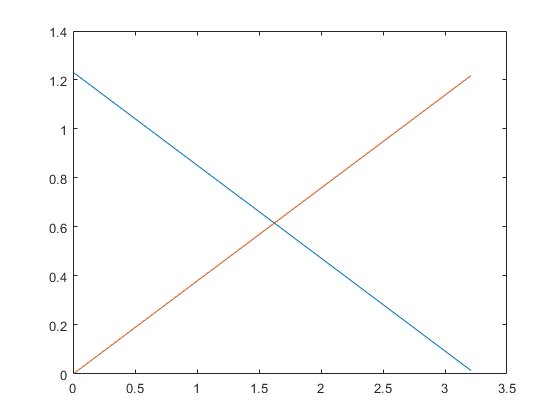

figure();
plot(s,xt);
hold on
plot(s,yt);

figure()
l = LinearSpline();
s = [0: 0.01: l.getLength()]
[x,y] = l.getPoint(s)
plot(s,x)